# OFDM Transmitter and Receiver

a bits are split into transport , and OFDM-modulated. Control signals are multiplexed in with the data 

% Clear persistent state variables and buffers, and close all figures
clear helperOFDMRx helperOFDMRxFrontEnd helperOFDMRxSearch helperOFDMChannel helperOFDMFrequencyOffset clear helperOFDMChannelEstimation
close all;

userParam = struct( ...
    'BWIndex',          5, ...   % Index corresponding to desired bandwidth
    'modOrder',         64, ...   % Subcarrier constellation modulation order
    'codeRateIndex',    0, ...   % Code rate index corresponding to desired rate
    'numSymPerFrame',   15, ...   % Number of OFDM symbols per frame
    'numFrames',        500 ...
    , ...   % Number of frames to be generated for simulation (12-500)
    'fc',               1000000000, ...   % Carrier frequency (Hz)
    'enableFading',     true                 , ...   % Enable/disable channel fading
    'chanVisual',       "Off", ...   % Channel fading visualization option
    'enableCFO',        true                 , ...   % Enable/disable carrier frequency offset compensation
    'enableCPE',        true                 , ...   % Enable/disable common phase error compensation
    'enableScopes',     true                 , ...   % Enable/disable scopes
    'verbosity',        1);      % Diagnostic output verbosity

## Mobile Environment and Impairments

Specify the impairments and the desired signal-to-noise ratio (SNR) assuming no channel loss or fading. Specify the SNR as a scalar value or create a vector of SNR values to run multiple simulations at different SNRs, and then create a BER plot. Note that sync symbol detection at low SNRs may not be possible.

The velocity inversely affects the channel coherence time (specifically, the amount of time the channel distortion is roughly constant). Since the beginning of each frame contains a reference signal to measure the channel distortion, set the velocity so that the coherence time is sufficiently greater than the frame period (controlled by the number of symbols per frame). To select a velocity, consider a generally accepted estimate of the coherence time $T_c=c/(v*f)$, where $c$ is the speed of light, $v$ is the velocity, and $f$ is the carrier frequency.

The frequency offset is the difference between the transmitter and receiver at the baseband frequency. This parameter is commonly expressed in parts per million (ppm). For example, a 100 Hz offset with respect to a sampling frequency of 30.72 MHz yields an offset of 3.25 ppm.

The fading path delays and gains control the number of paths and average gain in dB of each path. A scalar entry for each constitutes a flat fading channel, and a vector specifies multi-path fading. You can see the effects of flat vs. multi-path fading by enabling the scopes and comparing the spectrum plots. Multipath fading causes nulls in some parts of the transmitted spectrum; interleaving helps to spread user data across all frequencies, so that some of the redundant bits are received on unaffected subcarriers. Decreasing the coding rate in the system parameters also helps to generate more redundant bits and increase the chances of error correction, but at the cost of lower user data throughput.

SNRdB = 25:5:25; % SNR in dB
v     = 40; % mobile velocity (km/h)     
foff  = 3.25; % frequency offset (ppm)
fadingPathDelays =  [0 0.1e-6 0.3e-6];
fadingPathGains  =  [0 1 -9];

BERResults = zeros(size(SNRdB));

## Populate Parameter Structure

The helper function `helperOFDMSetParameters` configures the system parameters common to the transmitter and receiver.

Coding parameters specify the channel coding parameters that are applied to the data payload for scrambling, interleaving, and convolutional encoding purposes. These parameters are shared between the transmitter and receiver. The system uses a 7th-degree scrambler polynomial, interleaving depth of 12 for header data and 18 for payload data, a base convolutional coding rate of 1/2, and a 32-bit CRC.

[sysParam, txParam] = helperOFDMSetParameters(userParam);

[~,codeParam] = helperOFDMGetTables(userParam.BWIndex,userParam.codeRateIndex);
codeRate = codeParam.codeRate; % Coding rate

fprintf('\nTransmitting at %d MHz with an occupied bandwidth of %d MHz\n', ...
    sysParam.fc/1e6,sysParam.scs*sysParam.usedSubCarr/1e6);


Transmitting at 1000 MHz with an occupied bandwidth of 18 MHz



% Calculate fading channel impairments
KPH_TO_MPS = (1000/3600);
fsamp = sysParam.scs*sysParam.FFTLen;       % sample rate of signal
T = (sysParam.FFTLen+sysParam.CPLen)/fsamp; % symbol duration (s)
fmax = v * KPH_TO_MPS * sysParam.fc / physconst('LightSpeed');  % Maximum Doppler shift of diffuse components (Hz)

% Set up scopes
if userParam.enableScopes
    % Set up constellation diagram object
    refConstHeader = qammod(0:1,2,UnitAveragePower=true); % header is always BPSK
    refConstData   = qammod(0:txParam.modOrder-1,txParam.modOrder,UnitAveragePower=true);
    constDiag = comm.ConstellationDiagram(2, ...
        "ChannelNames",{'Header','Data'}, ...
        "ReferenceConstellation",{refConstHeader,refConstData}, ...
        "ShowLegend",true, ...
        "EnableMeasurements",true);

    % Set up spectrum analyzer visualization object
    sa = spectrumAnalyzer( ...
        'Name',             'Signal Spectra', ...
        'Title',            'Transmitted and Received Signal', ...
        'SpectrumType',     'Power', ...
        'FrequencySpan',    'Full', ...
        'SampleRate',       fsamp, ...
        'ShowLegend',       true, ...
        'Position',         [100 600 800 500], ...
        'ChannelNames',     {'Transmitted','Received'});
end

## Initialize States and Process Data Frames

For each SNR specified in the user settings, the receiver begins in an unsynchronized, unassociated, and unconnected state. The receiver must detect the start of a frame through sync symbol detection and synchronize the receive sample buffers to begin storing samples when the beginning of the transmit frame is received. The receiver must then estimate the frequency offset and align its internal clock to match the transmitter clock; it is then considered "camped" (associated) with the base station. Finally, after header information is received and decoded, the receiver transitions to a connected state and begins decoding data.

Once connected, the simulation loops though the frame processing to generate a transmit frame, distort the output samples through a channel filter, and process the received samples to produce the transport block bitstream.

% Initialize transmitter
txObj = helperOFDMTxInit(sysParam);


% Initialize receiver
rxObj = helperOFDMRxInit(sysParam);
    
for simLoopIdx = 1:length(SNRdB)
    % Configure the channel
    chanParam = struct( ...
        'SNR',       SNRdB(simLoopIdx), ...
        'foff',      foff, ...       % normalized frequency offset (ppm)
        'doppler',   fmax*T, ...     % normalized Doppler frequency
        'pathDelay', fadingPathDelays, ...
        'pathGain',  fadingPathGains);
    fprintf('Configuring the fading AWGN channel at %d dB SNR and %d kph...\n', SNRdB(simLoopIdx), v);

    sysParam.txDataBits = []; % clear tx data buffer

    sysParam.timingAdvance = (sysParam.FFTLen + sysParam.CPLen) * ...
        sysParam.numSymPerFrame; % set sample buffer timing advance
    
    % Instantiate an ErrorRate object to cumulatively track BER
    errorRate = comm.ErrorRate();

    fprintf('Transmitting %d frames with transport block size of %d bits per frame...\n', ...
        sysParam.numFrames,sysParam.trBlkSize);
    fprintf('Searching for synchronization symbol...');
    
    % Loop through all frames. Generate one extra frame to obtain the
    % reference symbol for channel estimates of the last frame.
    for frameNum = 1:sysParam.numFrames+1
        sysParam.frameNum = frameNum;

Configuring the fading AWGN channel at 25 dB SNR and 40 kph...


Transmitting 500 frames with transport block size of 41362 bits per frame...


Searching for synchronization symbol...

## Payload Generation

User data is packed into a transport block, which is transmitted once per frame. The size of the transport block depends on the number of active subcarriers, number of pilot subcarriers that occupy active subcarriers, modulation order, coding rate, CRC length, encoder constraint length, and number of data symbols per frame.

Randomly generated data is used to pack the transport blocks, but custom data can be sent if desired. The data must be split into transport blocks, with the last block padded with zeros if necessary.

        % Generate random data to transmit. Replace with user data if desired.
        rng(123)
        txParam.txDataBits  = randi([0 1],sysParam.trBlkSize,1);

        % Store data bits for BER calculations
        sysParam.txDataBits = [sysParam.txDataBits; txParam.txDataBits];
        sysParam.txDataBits = sysParam.txDataBits(max(1,end-2*sysParam.trBlkSize):end);


## Transmitter Processing

The transmission grid populates signals and channels on a per-frame basis. The figure below shows one transmission frame of 24 OFDM symbols with FFT length of 256.

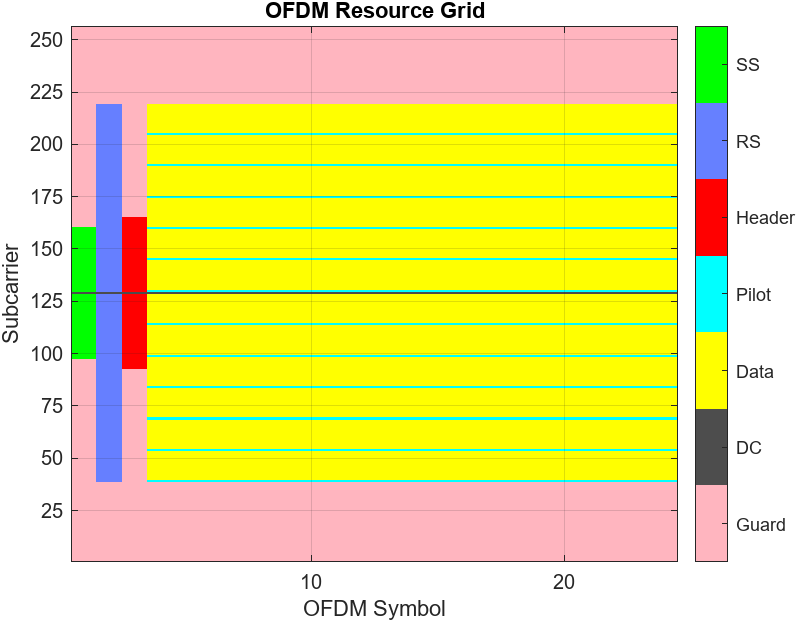

**Synchronization Symbol (SS)**

A synchronization (sync) signal is transmitted as the first symbol in the frame and consists of a 62-subcarrier signal centered at DC. This signal is designed to be bandwidth agnostic, meaning that all transmitters can transmit this signal regardless of the allocated bandwidth for that cell. The signal is meant to be detected by receivers to positively detect the cell signal and identify the frame boundary (the start of the frame).

**Reference Symbol (RS)**

A reference symbol is transmitted next. The reference symbol provides the receiver with a known reference to measure the channel distortion between the transmitter and receiver. The receiver processing can compensate for that distortion to recover the original signal as much as possible.

**Header Symbol**

The header conveys the bandwidth, subcarrier modulation scheme, and code rate of the OFDM data symbols to the receiver so that the receiver can properly decode the remainder of the frame. The information is important enough that it is transmitted with large signaling and coding margins to maximize correct decoding. Therefore, the symbol is coded at 1/2 rate with wide interleaving and modulated using BPSK. Since the channel distortion may change over time, the header symbol is transmitted immediately after the reference symbol to maximize the probability of correct reception. Because the bandwidth is not yet known, the header is always transmitted with a 72-subcarrier signal centered at DC.

**Pilot Signals**

Finally, to combat phase jitter seen at higher transmission frequencies, a pilot is transmitted at fixed subcarrier intervals within the data symbols to provide a phase reference to the receiver.

**DC and Guard Subcarriers**

Null subcarriers at the edge of the transmission spectrum are used to constrain spectral energy to a specified bandwidth. The subcarrier at DC is also nulled to keep the signal energy to within the linear range of the power amplifier.

**Transmitter Architecture**

The transmitter generates both control signals (sync, reference, header, and pilots) and data signals (transport block). The sync, reference, and header symbols are generated separately and time-multiplexed with the data symbols.

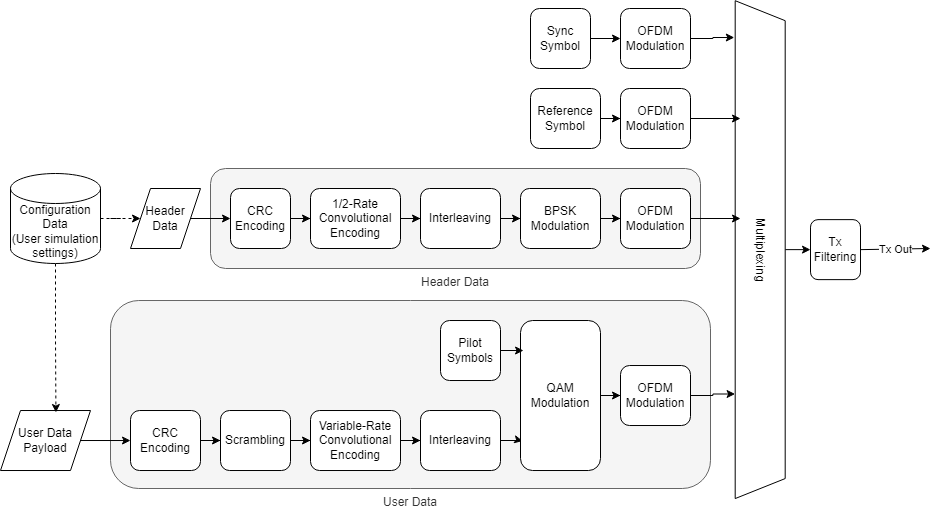

The data symbols comprise a single user populating a single transport block of data transmitted once per frame. A `comm.CRCGenerator` object computes the CRC for the transport block payload and appends it to the payload. The data is additively scrambled using a `comm.PNSequence` object to distribute the data power evenly across the transmission spectrum.  Interleaving is done with the `reshape` function to resist burst errors caused by deep fades. Convolutional encoding adds redundant bits for forward error correction and is done with the `convenc` function. Puncturing of the data increases data throughput by reducing the number of redundant bits. The transport block is modulated using the `qammod` function and is ready for transmission in an OFDM frame. All signals are OFDM-modulated using the `ofdmmod` function. The signal is filtered to reduce out-of-band emissions using dsp.`FIRFilter`, with coefficients generated using the `firpmord` and `firpm` filter design functions.

        % Transmit data
        [txOut,txGrid,txDiagnostics] = helperOFDMTx(txParam,sysParam,txObj);

## Apply Channel and Hardware Impairments

Introduce impairments to corrupt the transmitted signal, including fading, additive white Gaussian noise (AWGN), and carrier frequency offset. The impulse response of the channel is optionally shown to visualize potential inter-symbol interference leaking out of the cyclic prefix region of the OFDM symbol.

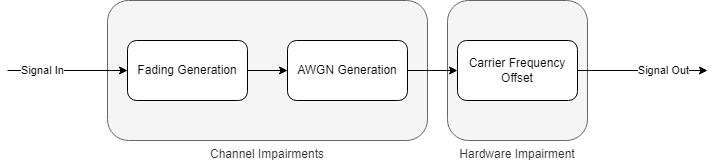

**Fading**

A `comm.RayleighChannel` object is used to apply Rayleigh fading to the transmitted output. Using an object allows for channel statistics to be retained internally between calls to the object. Because the Doppler frequency is a function of transmission frequency, the normalized Doppler parameter is used to convey the Doppler frequency and more easily show the impact of mobile speed independent of the carrier frequency.

**Additive Noise**

The `awgn` function is used to apply AWGN to the faded signal. The input power into the awgn function is calculated as a function of per-subcarrier constellation power and number of occupied subcarriers. This input power is passed to the awgn function, along with the target SNR, to get the desired signal SNR.

**Carrier Frequency Offset**

Finally, the frequency offset is applied within the channel block. Use the `comm.PhaseFrequencyOffset` function to rotate the time-domain signal by the desired frequency.

        % Process one frame of samples through channel
        %chanOut = helperOFDMChannel(txOut,chanParam,sysParam);

        
        fileIdx = frameNum;                                 % 2,3,4…
        matFile = fullfile('e3', sprintf('%d.mat',fileIdx));
        % matFile = fullfile('wired_b210', sprintf('%d.mat',fileIdx));
        % matFile = fullfile('chanests2wired', sprintf('%d.mat',fileIdx));
        % 
        if ~isfile(matFile)
            warning('Missing %s – stopping frame loop.', matFile);
            break;
        end
        % 
        S       = load(matFile,'chanEstCurrent');               
        chanOut = double(S.chanEstCurrent(:));  
        % fprintf('Loaded channel estimate from %s\n', matFile);
        % % ───────────────────────────────────────────────────────────────────
        
        % 
        % 
        % % ─── Replace the simulated channel with your recorded estimates ───
        % fileIdx = frameNum;                                 % 2,3,4…
        % matFile = fullfile('', sprintf('%d.mat',fileIdx));
        % % 
        % if ~isfile(matFile)
        %     warning('Missing %s – stopping frame loop.', matFile);
        %     break;
        % end
        % % 
        % S       = load(matFile,'chanEstCurrent');               
        % chanOut = double(S.chanEstCurrent(:));  
        % % fprintf('Loaded channel estimate from %s\n', matFile);
        % % % ───────────────────────────────────────────────────────────────────



        

                

## Channel Visualization

Use the `spectrumAnalyzer` function to visualize the received spectrum after fading and noise are added to the transmitted signal. As the simulation runs, you can see how the received signal constellation is negatively affected by the spectral nulls caused by multipath fading.

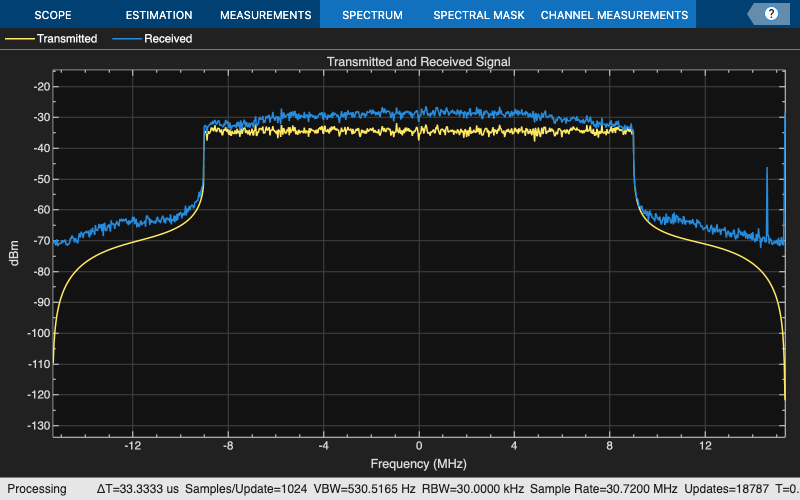

        if userParam.enableScopes
        % % 
          sa(txOut,chanOut(1:38400));
          
        end

## Receiver Processing

The receiver reverses the transmitter processing. It also must detect and correct distortions caused by asynchronous timing, frequency offset, noise, time-varying fading, frequency-selective fading, and phase jitter.

The signal is lowpass filtered to remove out-of-band energy that could introduce noise. At the start of the receiver simulation, sync signal detection is performed by time-domain correlation and thresholding to determine the start of the frame. Until the sync symbol is detected, the receiver is not "camped" to any base station.

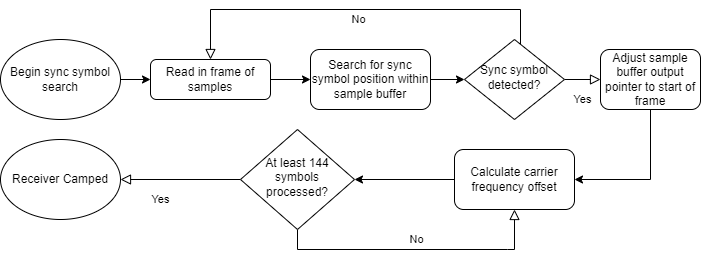

Following successful sync detection, 144 symbols are used by the automatic frequency correction (AFC) to estimate the frequency offset by detecting the phase shift between the cyclic prefix (a copy of the end of the symbol's samples that is transmitted at the beginning of an OFDM symbol) and the end of the symbol. Six symbols are used to obtain one frequency offset estimate, and the last 24 estimates are averaged to obtain the final filtered CFO estimate. Combined with knowledge of the duration of an OFDM symbol, the frequency offset can be estimated using inner product calculation. The frequency offset is then corrected with a numerically controlled oscillator using the `comm.PhaseFrequencyOffset` object. Once the signal is stable with respect to the timing offset and frequency offset, the receiver is considered camped and connected, and a complete frame is demodulated into OFDM subcarriers using `ofdmdemod`.

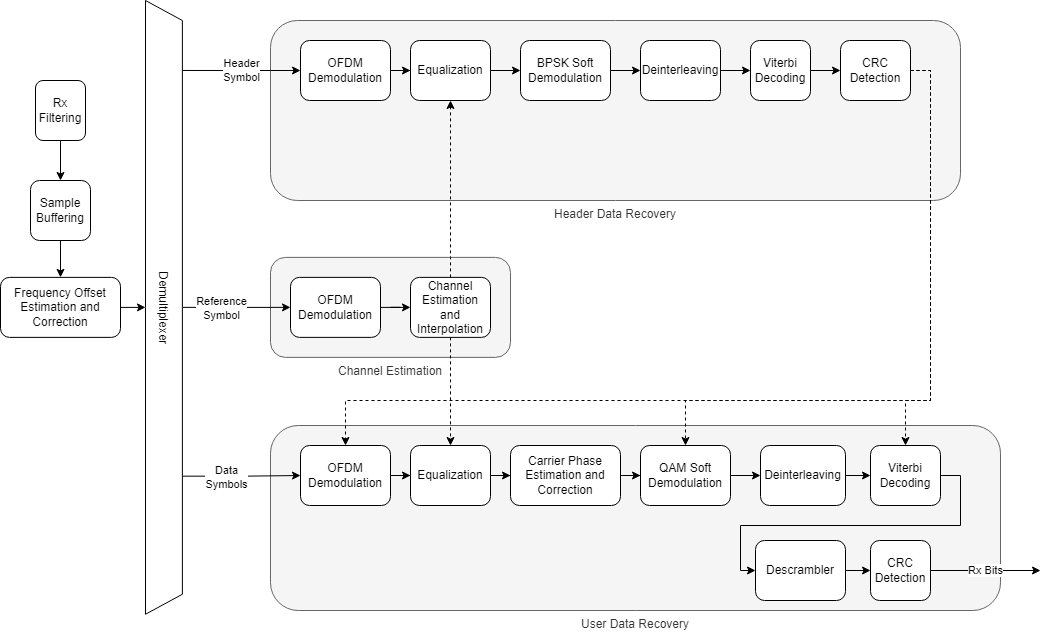

To combat time-varying fading, two reference symbols rom adjacent frames are used to estimate the channel at different points in time, and then the channel estimates in between the two reference symbols are linearly interpolated to provide the channel estimates for the header and data symbols. The symbols are then equalized using the channel estimates with `ofdmEqualize`.

The header is extracted and decoded to obtain the data symbol parameters such as FFT length, subcarrier modulation scheme, and code rate. The data symbols are then demodulated according to the header parameters.

The pilots within the data symbols are used to estimate the common phase error (CPE) typically caused by phase jitter in mmWave transmissions. CPE affects all subcarriers equally. The error is derotated to remove the CPE from the data symbols, and the data subcarriers are soft-decoded into log-likelihood ratios (LLRs) using the `qamdemod` function.

Once the bitstream is available, the bits are deinterleaved before maximum-likelihood decoding is performed using the `vitdec` function which implements the Viterbi algorithm. The bits are then descrambled, and the `comm.CRCDetector` object computes the CRC and compares it with the appended CRC within the payload for transport block verification.

        % Run the receiver front-end
        rxIn = helperOFDMRxFrontEnd(chanOut,sysParam,rxObj);
        
        % Run the receiver processing
            % Run the receiver processing
        disp(matFile)
        [rxDataBits,isConnected,toff,rxDiagnostics] = helperOFDMRx(rxIn,sysParam,rxObj);
        
        % ─── Clamp and sanitize timingAdvance ───────────────────────────────
        if isempty(toff) || ~isfinite(toff)
            toff = 1;       % default to start of buffer until sync locks
        end
        toff = round(toff);  % integer index
        % frameLen = samples per full frame
        frameLen = (sysParam.FFTLen + sysParam.CPLen) * sysParam.numSymPerFrame;
        % force 1 ≤ toff ≤ frameLen
        sysParam.timingAdvance = min( max( toff, 1 ), frameLen );
        % ─────────────────────────────────────────────────────────────────────
    



## Receiver Performance Visualization

Use the `comm.ConstellationDiagram` object to display the header constellation and data constellation in one plot. By varying the channel impairments, you can visualize the noise after receiver impairment compensation for all subcarriers superimposed on the plot. EVM and MER can be measured with respect to the reference constellation for each data modulation.

e3/1.mat



Sync symbol found.
Estimating carrier frequency offset ...

e3/2.mat


.

e3/3.mat


.

e3/4.mat


.

e3/5.mat


.

e3/6.mat


.

e3/7.mat


.

e3/8.mat


.

e3/9.mat


.

e3/10.mat


.

e3/11.mat


.

e3/12.mat



Receiver camped.


e3/13.mat


Detected and processing frame 13
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862085e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 13 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/13.mat


e3/14.mat


Detected and processing frame 14
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862138e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 14 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/14.mat


e3/15.mat


Detected and processing frame 15
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862946e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 15 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/15.mat


e3/16.mat


Detected and processing frame 16
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.863483e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 16 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/16.mat


e3/17.mat


Detected and processing frame 17
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.863761e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 17 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/17.mat


e3/18.mat


Detected and processing frame 18
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.863609e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 18 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/18.mat


e3/19.mat


Detected and processing frame 19
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.863421e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 19 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/19.mat


e3/20.mat


Detected and processing frame 20
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862926e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 20 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/20.mat


e3/21.mat


Detected and processing frame 21
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.863460e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 21 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/21.mat


e3/22.mat


Detected and processing frame 22
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.863554e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 22 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/22.mat


e3/23.mat


Detected and processing frame 23
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862743e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 23 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/23.mat


e3/24.mat


Detected and processing frame 24
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862641e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 24 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/24.mat


e3/25.mat


Detected and processing frame 25
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862146e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 25 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/25.mat


e3/26.mat


Detected and processing frame 26
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862847e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 26 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/26.mat


e3/27.mat


Detected and processing frame 27
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.863120e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 27 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/27.mat


e3/28.mat


Detected and processing frame 28
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862840e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 28 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/28.mat


e3/29.mat


Detected and processing frame 29
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862614e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 29 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/29.mat


e3/30.mat


Detected and processing frame 30
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862407e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 30 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/30.mat


e3/31.mat


Detected and processing frame 31
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862632e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 31 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/31.mat


e3/32.mat


Detected and processing frame 32
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862333e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 32 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/32.mat


e3/33.mat


Detected and processing frame 33
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.863933e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 33 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/33.mat


e3/34.mat


Detected and processing frame 34
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862470e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 34 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/34.mat


e3/35.mat


Detected and processing frame 35
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.863038e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 35 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/35.mat


e3/36.mat


Detected and processing frame 36
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862425e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 36 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/36.mat


e3/37.mat


Detected and processing frame 37
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862258e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 37 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/37.mat


e3/38.mat


Detected and processing frame 38
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862987e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 38 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/38.mat


e3/39.mat


Detected and processing frame 39
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862842e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 39 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/39.mat


e3/40.mat


Detected and processing frame 40
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862729e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 40 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/40.mat


e3/41.mat


Detected and processing frame 41
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861259e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 41 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/41.mat


e3/42.mat


Detected and processing frame 42
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862108e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 42 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/42.mat


e3/43.mat


Detected and processing frame 43
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860715e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 43 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/43.mat


e3/44.mat


Detected and processing frame 44
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862680e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 44 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/44.mat


e3/45.mat


Detected and processing frame 45
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861726e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 45 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/45.mat


e3/46.mat


Detected and processing frame 46
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862798e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 46 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/46.mat


e3/47.mat


Detected and processing frame 47
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861739e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 47 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/47.mat


e3/48.mat


Detected and processing frame 48
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862606e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 48 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/48.mat


e3/49.mat


Detected and processing frame 49
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861827e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 49 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/49.mat


e3/50.mat


Detected and processing frame 50
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861969e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 50 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/50.mat


e3/51.mat


Detected and processing frame 51
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861915e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 51 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/51.mat


e3/52.mat


Detected and processing frame 52
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861004e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 52 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/52.mat


e3/53.mat


Detected and processing frame 53
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861141e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 53 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/53.mat


e3/54.mat


Detected and processing frame 54
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860766e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 54 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/54.mat


e3/55.mat


Detected and processing frame 55
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860857e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 55 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/55.mat


e3/56.mat


Detected and processing frame 56
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860575e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 56 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/56.mat


e3/57.mat


Detected and processing frame 57
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861358e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 57 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/57.mat


e3/58.mat


Detected and processing frame 58
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860257e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 58 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/58.mat


e3/59.mat


Detected and processing frame 59
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861941e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 59 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/59.mat


e3/60.mat


Detected and processing frame 60
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861754e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 60 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/60.mat


e3/61.mat


Detected and processing frame 61
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861769e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 61 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/61.mat


e3/62.mat


Detected and processing frame 62
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861788e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 62 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/62.mat


e3/63.mat


Detected and processing frame 63
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.863297e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 63 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/63.mat


e3/64.mat


Detected and processing frame 64
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861968e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 64 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/64.mat


e3/65.mat


Detected and processing frame 65
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862347e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 65 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/65.mat


e3/66.mat


Detected and processing frame 66
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862213e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 66 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/66.mat


e3/67.mat


Detected and processing frame 67
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861094e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 67 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/67.mat


e3/68.mat


Detected and processing frame 68
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860939e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 68 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/68.mat


e3/69.mat


Detected and processing frame 69
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862022e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 69 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/69.mat


e3/70.mat


Detected and processing frame 70
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860561e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 70 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/70.mat


e3/71.mat


Detected and processing frame 71
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860658e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 71 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/71.mat


e3/72.mat


Detected and processing frame 72
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860634e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 72 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/72.mat


e3/73.mat


Detected and processing frame 73
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860877e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 73 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/73.mat


e3/74.mat


Detected and processing frame 74
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860915e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 74 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/74.mat


e3/75.mat


Detected and processing frame 75
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861704e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 75 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/75.mat


e3/76.mat


Detected and processing frame 76
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861034e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 76 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC failed


Loaded channel estimate from e3/76.mat


e3/77.mat


Detected and processing frame 77
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860280e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 77 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/77.mat


e3/78.mat


Detected and processing frame 78
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860879e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 78 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/78.mat


e3/79.mat


Detected and processing frame 79
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859777e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 79 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/79.mat


e3/80.mat


Detected and processing frame 80
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860594e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 80 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/80.mat


e3/81.mat


Detected and processing frame 81
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858958e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 81 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/81.mat


e3/82.mat


Detected and processing frame 82
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858777e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 82 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/82.mat


e3/83.mat


Detected and processing frame 83
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857692e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 83 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/83.mat


e3/84.mat


Detected and processing frame 84
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858768e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 84 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/84.mat


e3/85.mat


Detected and processing frame 85
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857205e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 85 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/85.mat


e3/86.mat


Detected and processing frame 86
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858496e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 86 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/86.mat


e3/87.mat


Detected and processing frame 87
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856443e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 87 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/87.mat


e3/88.mat


Detected and processing frame 88
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857370e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 88 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/88.mat


e3/89.mat


Detected and processing frame 89
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855882e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 89 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/89.mat


e3/90.mat


Detected and processing frame 90
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856723e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 90 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/90.mat


e3/91.mat


Detected and processing frame 91
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855807e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 91 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/91.mat


e3/92.mat


Detected and processing frame 92
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856540e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 92 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/92.mat


e3/93.mat


Detected and processing frame 93
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855797e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 93 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/93.mat


e3/94.mat


Detected and processing frame 94
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855315e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 94 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/94.mat


e3/95.mat


Detected and processing frame 95
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855895e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 95 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/95.mat


e3/96.mat


Detected and processing frame 96
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855258e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 96 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/96.mat


e3/97.mat


Detected and processing frame 97
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854168e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 97 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/97.mat


e3/98.mat


Detected and processing frame 98
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854697e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 98 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/98.mat


e3/99.mat


Detected and processing frame 99
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855428e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 99 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/99.mat


e3/100.mat


Detected and processing frame 100
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854896e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 100 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/100.mat


e3/101.mat


Detected and processing frame 101
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854005e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 101 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC failed


Loaded channel estimate from e3/101.mat


e3/102.mat


Detected and processing frame 102
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854146e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 102 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/102.mat


e3/103.mat


Detected and processing frame 103
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858497e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 103 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/103.mat


e3/104.mat


Detected and processing frame 104
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855897e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 104 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/104.mat


e3/105.mat


Detected and processing frame 105
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861036e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 105 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/105.mat


e3/106.mat


Detected and processing frame 106
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857068e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 106 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/106.mat


e3/107.mat


Detected and processing frame 107
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860635e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 107 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/107.mat


e3/108.mat


Detected and processing frame 108
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856707e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 108 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/108.mat


e3/109.mat


Detected and processing frame 109
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861572e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 109 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/109.mat


e3/110.mat


Detected and processing frame 110
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858523e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 110 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/110.mat


e3/111.mat


Detected and processing frame 111
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858002e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 111 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/111.mat


e3/112.mat


Detected and processing frame 112
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857152e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 112 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/112.mat


e3/113.mat


Detected and processing frame 113
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857453e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 113 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/113.mat


e3/114.mat


Detected and processing frame 114
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857055e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 114 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/114.mat


e3/115.mat


Detected and processing frame 115
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856685e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 115 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/115.mat


e3/116.mat


Detected and processing frame 116
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857257e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 116 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/116.mat


e3/117.mat


Detected and processing frame 117
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856648e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 117 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/117.mat


e3/118.mat


Detected and processing frame 118
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856204e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 118 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/118.mat


e3/119.mat


Detected and processing frame 119
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856562e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 119 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/119.mat


e3/120.mat


Detected and processing frame 120
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856609e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 120 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/120.mat


e3/121.mat


Detected and processing frame 121
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855780e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 121 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/121.mat


e3/122.mat


Detected and processing frame 122
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854718e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 122 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/122.mat


e3/123.mat


Detected and processing frame 123
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855440e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 123 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/123.mat


e3/124.mat


Detected and processing frame 124
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855107e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 124 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/124.mat


e3/125.mat


Detected and processing frame 125
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855679e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 125 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/125.mat


e3/126.mat


Detected and processing frame 126
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854167e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 126 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/126.mat


e3/127.mat


Detected and processing frame 127
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854503e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 127 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/127.mat


e3/128.mat


Detected and processing frame 128
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.852965e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 128 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/128.mat


e3/129.mat


Detected and processing frame 129
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854447e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 129 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/129.mat


e3/130.mat


Detected and processing frame 130
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.852827e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 130 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/130.mat


e3/131.mat


Detected and processing frame 131
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854244e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 131 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/131.mat


e3/132.mat


Detected and processing frame 132
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.852382e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 132 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/132.mat


e3/133.mat


Detected and processing frame 133
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.853056e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 133 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/133.mat


e3/134.mat


Detected and processing frame 134
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.851905e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 134 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/134.mat


e3/135.mat


Detected and processing frame 135
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.853006e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 135 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/135.mat


e3/136.mat


Detected and processing frame 136
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.852053e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 136 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/136.mat


e3/137.mat


Detected and processing frame 137
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.852555e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 137 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/137.mat


e3/138.mat


Detected and processing frame 138
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.851949e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 138 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/138.mat


e3/139.mat


Detected and processing frame 139
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.851614e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 139 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/139.mat


e3/140.mat


Detected and processing frame 140
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.851376e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 140 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/140.mat


e3/141.mat


Detected and processing frame 141
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.851604e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 141 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/141.mat


e3/142.mat


Detected and processing frame 142
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.851368e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 142 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/142.mat


e3/143.mat


Detected and processing frame 143
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.850963e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 143 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/143.mat


e3/144.mat


Detected and processing frame 144
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.851258e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 144 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/144.mat


e3/145.mat


Detected and processing frame 145
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.851228e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 145 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/145.mat


e3/146.mat


Detected and processing frame 146
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.851551e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 146 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/146.mat


e3/147.mat


Detected and processing frame 147
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.852661e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 147 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/147.mat


e3/148.mat


Detected and processing frame 148
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.851974e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 148 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/148.mat


e3/149.mat


Detected and processing frame 149
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.852159e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 149 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/149.mat


e3/150.mat


Detected and processing frame 150
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.852050e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 150 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/150.mat


e3/151.mat


Detected and processing frame 151
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.852445e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 151 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/151.mat


e3/152.mat


Detected and processing frame 152
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.852116e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 152 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/152.mat


e3/153.mat


Detected and processing frame 153
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.853044e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 153 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/153.mat


e3/154.mat


Detected and processing frame 154
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.853162e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 154 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/154.mat


e3/155.mat


Detected and processing frame 155
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.852154e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 155 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/155.mat


e3/156.mat


Detected and processing frame 156
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.853375e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 156 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/156.mat


e3/157.mat


Detected and processing frame 157
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.852372e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 157 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/157.mat


e3/158.mat


Detected and processing frame 158
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854266e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 158 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/158.mat


e3/159.mat


Detected and processing frame 159
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.853421e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 159 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/159.mat


e3/160.mat


Detected and processing frame 160
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854245e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 160 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/160.mat


e3/161.mat


Detected and processing frame 161
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.852973e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 161 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/161.mat


e3/162.mat


Detected and processing frame 162
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.853453e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 162 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/162.mat


e3/163.mat


Detected and processing frame 163
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.852616e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 163 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/163.mat


e3/164.mat


Detected and processing frame 164
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.853436e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 164 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/164.mat


e3/165.mat


Detected and processing frame 165
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.853729e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 165 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/165.mat


e3/166.mat


Detected and processing frame 166
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.853248e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 166 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/166.mat


e3/167.mat


Detected and processing frame 167
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.853342e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 167 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/167.mat


e3/168.mat


Detected and processing frame 168
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854512e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 168 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/168.mat


e3/169.mat


Detected and processing frame 169
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854871e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 169 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/169.mat


e3/170.mat


Detected and processing frame 170
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855274e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 170 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/170.mat


e3/171.mat


Detected and processing frame 171
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856089e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 171 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/171.mat


e3/172.mat


Detected and processing frame 172
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855524e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 172 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/172.mat


e3/173.mat


Detected and processing frame 173
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855583e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 173 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/173.mat


e3/174.mat


Detected and processing frame 174
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855379e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 174 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/174.mat


e3/175.mat


Detected and processing frame 175
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855729e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 175 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/175.mat


e3/176.mat


Detected and processing frame 176
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.853937e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 176 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/176.mat


e3/177.mat


Detected and processing frame 177
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854974e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 177 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/177.mat


e3/178.mat


Detected and processing frame 178
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.853440e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 178 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/178.mat


e3/179.mat


Detected and processing frame 179
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854124e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 179 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/179.mat


e3/180.mat


Detected and processing frame 180
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.853184e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 180 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/180.mat


e3/181.mat


Detected and processing frame 181
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.853384e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 181 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/181.mat


e3/182.mat


Detected and processing frame 182
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.853625e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 182 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/182.mat


e3/183.mat


Detected and processing frame 183
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854212e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 183 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/183.mat


e3/184.mat


Detected and processing frame 184
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854421e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 184 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/184.mat


e3/185.mat


Detected and processing frame 185
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.853441e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 185 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/185.mat


e3/186.mat


Detected and processing frame 186
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854974e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 186 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/186.mat


e3/187.mat


Detected and processing frame 187
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.853764e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 187 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/187.mat


e3/188.mat


Detected and processing frame 188
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855279e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 188 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/188.mat


e3/189.mat


Detected and processing frame 189
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854432e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 189 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/189.mat


e3/190.mat


Detected and processing frame 190
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855450e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 190 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/190.mat


e3/191.mat


Detected and processing frame 191
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854860e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 191 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/191.mat


e3/192.mat


Detected and processing frame 192
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856058e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 192 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/192.mat


e3/193.mat


Detected and processing frame 193
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855545e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 193 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/193.mat


e3/194.mat


Detected and processing frame 194
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855849e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 194 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/194.mat


e3/195.mat


Detected and processing frame 195
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855586e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 195 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/195.mat


e3/196.mat


Detected and processing frame 196
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855442e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 196 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/196.mat


e3/197.mat


Detected and processing frame 197
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855630e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 197 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/197.mat


e3/198.mat


Detected and processing frame 198
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855226e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 198 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/198.mat


e3/199.mat


Detected and processing frame 199
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854686e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 199 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/199.mat


e3/200.mat


Detected and processing frame 200
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854621e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 200 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/200.mat


e3/201.mat


Detected and processing frame 201
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855536e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 201 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC failed


Loaded channel estimate from e3/201.mat


e3/202.mat


Detected and processing frame 202
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854921e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 202 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/202.mat


e3/203.mat


Detected and processing frame 203
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856303e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 203 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/203.mat


e3/204.mat


Detected and processing frame 204
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856841e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 204 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/204.mat


e3/205.mat


Detected and processing frame 205
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856896e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 205 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/205.mat


e3/206.mat


Detected and processing frame 206
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857655e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 206 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/206.mat


e3/207.mat


Detected and processing frame 207
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858242e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 207 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/207.mat


e3/208.mat


Detected and processing frame 208
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858516e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 208 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/208.mat


e3/209.mat


Detected and processing frame 209
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858902e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 209 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/209.mat


e3/210.mat


Detected and processing frame 210
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858950e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 210 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/210.mat


e3/211.mat


Detected and processing frame 211
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859582e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 211 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/211.mat


e3/212.mat


Detected and processing frame 212
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858212e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 212 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC failed


Loaded channel estimate from e3/212.mat


e3/213.mat


Detected and processing frame 213
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859077e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 213 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/213.mat


e3/214.mat


Detected and processing frame 214
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862130e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 214 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/214.mat


e3/215.mat


Detected and processing frame 215
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859380e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 215 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/215.mat


e3/216.mat


Detected and processing frame 216
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862649e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 216 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/216.mat


e3/217.mat


Detected and processing frame 217
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858828e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 217 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/217.mat


e3/218.mat


Detected and processing frame 218
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862831e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 218 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/218.mat


e3/219.mat


Detected and processing frame 219
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859069e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 219 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/219.mat


e3/220.mat


Detected and processing frame 220
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862793e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 220 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/220.mat


e3/221.mat


Detected and processing frame 221
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859534e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 221 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/221.mat


e3/222.mat


Detected and processing frame 222
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859561e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 222 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/222.mat


e3/223.mat


Detected and processing frame 223
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859384e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 223 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/223.mat


e3/224.mat


Detected and processing frame 224
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858163e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 224 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/224.mat


e3/225.mat


Detected and processing frame 225
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858559e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 225 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/225.mat


e3/226.mat


Detected and processing frame 226
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857640e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 226 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/226.mat


e3/227.mat


Detected and processing frame 227
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858362e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 227 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/227.mat


e3/228.mat


Detected and processing frame 228
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857008e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 228 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/228.mat


e3/229.mat


Detected and processing frame 229
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858299e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 229 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/229.mat


e3/230.mat


Detected and processing frame 230
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856817e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 230 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/230.mat


e3/231.mat


Detected and processing frame 231
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857578e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 231 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/231.mat


e3/232.mat


Detected and processing frame 232
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857298e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 232 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/232.mat


e3/233.mat


Detected and processing frame 233
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859204e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 233 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/233.mat


e3/234.mat


Detected and processing frame 234
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858509e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 234 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/234.mat


e3/235.mat


Detected and processing frame 235
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858619e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 235 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/235.mat


e3/236.mat


Detected and processing frame 236
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858086e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 236 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/236.mat


e3/237.mat


Detected and processing frame 237
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858632e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 237 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/237.mat


e3/238.mat


Detected and processing frame 238
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858166e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 238 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/238.mat


e3/239.mat


Detected and processing frame 239
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859554e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 239 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/239.mat


e3/240.mat


Detected and processing frame 240
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859308e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 240 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/240.mat


e3/241.mat


Detected and processing frame 241
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858506e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 241 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/241.mat


e3/242.mat


Detected and processing frame 242
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857659e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 242 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/242.mat


e3/243.mat


Detected and processing frame 243
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858032e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 243 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/243.mat


e3/244.mat


Detected and processing frame 244
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857888e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 244 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/244.mat


e3/245.mat


Detected and processing frame 245
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858190e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 245 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/245.mat


e3/246.mat


Detected and processing frame 246
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858200e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 246 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/246.mat


e3/247.mat


Detected and processing frame 247
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857578e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 247 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/247.mat


e3/248.mat


Detected and processing frame 248
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857390e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 248 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/248.mat


e3/249.mat


Detected and processing frame 249
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858784e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 249 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/249.mat


e3/250.mat


Detected and processing frame 250
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857400e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 250 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/250.mat


e3/251.mat


Detected and processing frame 251
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857644e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 251 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/251.mat


e3/252.mat


Detected and processing frame 252
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856750e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 252 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/252.mat


e3/253.mat


Detected and processing frame 253
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857453e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 253 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/253.mat


e3/254.mat


Detected and processing frame 254
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857958e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 254 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/254.mat


e3/255.mat


Detected and processing frame 255
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859148e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 255 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/255.mat


e3/256.mat


Detected and processing frame 256
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858389e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 256 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/256.mat


e3/257.mat


Detected and processing frame 257
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857389e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 257 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/257.mat


e3/258.mat


Detected and processing frame 258
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857465e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 258 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/258.mat


e3/259.mat


Detected and processing frame 259
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857486e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 259 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/259.mat


e3/260.mat


Detected and processing frame 260
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857842e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 260 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/260.mat


e3/261.mat


Detected and processing frame 261
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857461e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 261 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/261.mat


e3/262.mat


Detected and processing frame 262
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857427e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 262 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/262.mat


e3/263.mat


Detected and processing frame 263
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855554e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 263 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/263.mat


e3/264.mat


Detected and processing frame 264
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856003e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 264 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/264.mat


e3/265.mat


Detected and processing frame 265
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.854855e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 265 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/265.mat


e3/266.mat


Detected and processing frame 266
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856772e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 266 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/266.mat


e3/267.mat


Detected and processing frame 267
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856239e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 267 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/267.mat


e3/268.mat


Detected and processing frame 268
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857172e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 268 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/268.mat


e3/269.mat


Detected and processing frame 269
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857919e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 269 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/269.mat


e3/270.mat


Detected and processing frame 270
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859098e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 270 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/270.mat


e3/271.mat


Detected and processing frame 271
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859021e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 271 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/271.mat


e3/272.mat


Detected and processing frame 272
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860475e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 272 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/272.mat


e3/273.mat


Detected and processing frame 273
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861332e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 273 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/273.mat


e3/274.mat


Detected and processing frame 274
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861168e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 274 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/274.mat


e3/275.mat


Detected and processing frame 275
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861169e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 275 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/275.mat


e3/276.mat


Detected and processing frame 276
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862050e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 276 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/276.mat


e3/277.mat


Detected and processing frame 277
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860983e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 277 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/277.mat


e3/278.mat


Detected and processing frame 278
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860705e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 278 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/278.mat


e3/279.mat


Detected and processing frame 279
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860997e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 279 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/279.mat


e3/280.mat


Detected and processing frame 280
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859863e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 280 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/280.mat


e3/281.mat


Detected and processing frame 281
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861460e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 281 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/281.mat


e3/282.mat


Detected and processing frame 282
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861863e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 282 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/282.mat


e3/283.mat


Detected and processing frame 283
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862454e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 283 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/283.mat


e3/284.mat


Detected and processing frame 284
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861993e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 284 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/284.mat


e3/285.mat


Detected and processing frame 285
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862394e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 285 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/285.mat


e3/286.mat


Detected and processing frame 286
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861439e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 286 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/286.mat


e3/287.mat


Detected and processing frame 287
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862062e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 287 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/287.mat


e3/288.mat


Detected and processing frame 288
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861741e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 288 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/288.mat


e3/289.mat


Detected and processing frame 289
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861267e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 289 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/289.mat


e3/290.mat


Detected and processing frame 290
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860245e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 290 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/290.mat


e3/291.mat


Detected and processing frame 291
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859446e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 291 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/291.mat


e3/292.mat


Detected and processing frame 292
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859533e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 292 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/292.mat


e3/293.mat


Detected and processing frame 293
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858718e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 293 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/293.mat


e3/294.mat


Detected and processing frame 294
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860107e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 294 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/294.mat


e3/295.mat


Detected and processing frame 295
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858569e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 295 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/295.mat


e3/296.mat


Detected and processing frame 296
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860436e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 296 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/296.mat


e3/297.mat


Detected and processing frame 297
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860148e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 297 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/297.mat


e3/298.mat


Detected and processing frame 298
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861501e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 298 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/298.mat


e3/299.mat


Detected and processing frame 299
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861107e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 299 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC failed


Loaded channel estimate from e3/299.mat


e3/300.mat


Detected and processing frame 300
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862096e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 300 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/300.mat


e3/301.mat


Detected and processing frame 301
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862346e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 301 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/301.mat


e3/302.mat


Detected and processing frame 302
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862986e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 302 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/302.mat


e3/303.mat


Detected and processing frame 303
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.863593e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 303 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/303.mat


e3/304.mat


Detected and processing frame 304
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862358e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 304 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/304.mat


e3/305.mat


Detected and processing frame 305
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862949e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 305 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/305.mat


e3/306.mat


Detected and processing frame 306
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861780e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 306 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/306.mat


e3/307.mat


Detected and processing frame 307
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862548e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 307 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/307.mat


e3/308.mat


Detected and processing frame 308
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862666e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 308 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/308.mat


e3/309.mat


Detected and processing frame 309
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.863039e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 309 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/309.mat


e3/310.mat


Detected and processing frame 310
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862624e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 310 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/310.mat


e3/311.mat


Detected and processing frame 311
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.863521e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 311 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/311.mat


e3/312.mat


Detected and processing frame 312
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.864070e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 312 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/312.mat


e3/313.mat


Detected and processing frame 313
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.863716e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 313 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/313.mat


e3/314.mat


Detected and processing frame 314
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.864552e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 314 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/314.mat


e3/315.mat


Detected and processing frame 315
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.864285e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 315 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/315.mat


e3/316.mat


Detected and processing frame 316
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.864239e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 316 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/316.mat


e3/317.mat


Detected and processing frame 317
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.863095e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 317 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/317.mat


e3/318.mat


Detected and processing frame 318
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.864141e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 318 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/318.mat


e3/319.mat


Detected and processing frame 319
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862659e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 319 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/319.mat


e3/320.mat


Detected and processing frame 320
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862759e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 320 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/320.mat


e3/321.mat


Detected and processing frame 321
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862414e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 321 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/321.mat


e3/322.mat


Detected and processing frame 322
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862921e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 322 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/322.mat


e3/323.mat


Detected and processing frame 323
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862135e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 323 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/323.mat


e3/324.mat


Detected and processing frame 324
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862824e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 324 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/324.mat


e3/325.mat


Detected and processing frame 325
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862136e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 325 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/325.mat


e3/326.mat


Detected and processing frame 326
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862611e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 326 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/326.mat


e3/327.mat


Detected and processing frame 327
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862166e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 327 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/327.mat


e3/328.mat


Detected and processing frame 328
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861468e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 328 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/328.mat


e3/329.mat


Detected and processing frame 329
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861407e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 329 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/329.mat


e3/330.mat


Detected and processing frame 330
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861280e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 330 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/330.mat


e3/331.mat


Detected and processing frame 331
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860768e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 331 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/331.mat


e3/332.mat


Detected and processing frame 332
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860437e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 332 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/332.mat


e3/333.mat


Detected and processing frame 333
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861140e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 333 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/333.mat


e3/334.mat


Detected and processing frame 334
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860256e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 334 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/334.mat


e3/335.mat


Detected and processing frame 335
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859810e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 335 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/335.mat


e3/336.mat


Detected and processing frame 336
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859984e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 336 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/336.mat


e3/337.mat


Detected and processing frame 337
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859998e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 337 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/337.mat


e3/338.mat


Detected and processing frame 338
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859557e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 338 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/338.mat


e3/339.mat


Detected and processing frame 339
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859974e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 339 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/339.mat


e3/340.mat


Detected and processing frame 340
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858962e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 340 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/340.mat


e3/341.mat


Detected and processing frame 341
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859567e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 341 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/341.mat


e3/342.mat


Detected and processing frame 342
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859068e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 342 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/342.mat


e3/343.mat


Detected and processing frame 343
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859297e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 343 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/343.mat


e3/344.mat


Detected and processing frame 344
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859314e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 344 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/344.mat


e3/345.mat


Detected and processing frame 345
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859241e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 345 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/345.mat


e3/346.mat


Detected and processing frame 346
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858920e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 346 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC failed


Loaded channel estimate from e3/346.mat


e3/347.mat


Detected and processing frame 347
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860969e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 347 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/347.mat


e3/348.mat


Detected and processing frame 348
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860101e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 348 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/348.mat


e3/349.mat


Detected and processing frame 349
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860680e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 349 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/349.mat


e3/350.mat


Detected and processing frame 350
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859781e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 350 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/350.mat


e3/351.mat


Detected and processing frame 351
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861868e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 351 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/351.mat


e3/352.mat


Detected and processing frame 352
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859859e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 352 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/352.mat


e3/353.mat


Detected and processing frame 353
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861978e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 353 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/353.mat


e3/354.mat


Detected and processing frame 354
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859887e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 354 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/354.mat


e3/355.mat


Detected and processing frame 355
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859929e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 355 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/355.mat


e3/356.mat


Detected and processing frame 356
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859783e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 356 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/356.mat


e3/357.mat


Detected and processing frame 357
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859964e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 357 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/357.mat


e3/358.mat


Detected and processing frame 358
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859072e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 358 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/358.mat


e3/359.mat


Detected and processing frame 359
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858653e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 359 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/359.mat


e3/360.mat


Detected and processing frame 360
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859228e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 360 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/360.mat


e3/361.mat


Detected and processing frame 361
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858694e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 361 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/361.mat


e3/362.mat


Detected and processing frame 362
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858848e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 362 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/362.mat


e3/363.mat


Detected and processing frame 363
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858569e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 363 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/363.mat


e3/364.mat


Detected and processing frame 364
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859261e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 364 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/364.mat


e3/365.mat


Detected and processing frame 365
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859580e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 365 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/365.mat


e3/366.mat


Detected and processing frame 366
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859775e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 366 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/366.mat


e3/367.mat


Detected and processing frame 367
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859375e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 367 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/367.mat


e3/368.mat


Detected and processing frame 368
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859749e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 368 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/368.mat


e3/369.mat


Detected and processing frame 369
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859878e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 369 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/369.mat


e3/370.mat


Detected and processing frame 370
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859090e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 370 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/370.mat


e3/371.mat


Detected and processing frame 371
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860056e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 371 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/371.mat


e3/372.mat


Detected and processing frame 372
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860013e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 372 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/372.mat


e3/373.mat


Detected and processing frame 373
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858815e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 373 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/373.mat


e3/374.mat


Detected and processing frame 374
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859291e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 374 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/374.mat


e3/375.mat


Detected and processing frame 375
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858777e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 375 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/375.mat


e3/376.mat


Detected and processing frame 376
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859338e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 376 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/376.mat


e3/377.mat


Detected and processing frame 377
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857838e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 377 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/377.mat


e3/378.mat


Detected and processing frame 378
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859330e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 378 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/378.mat


e3/379.mat


Detected and processing frame 379
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857811e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 379 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/379.mat


e3/380.mat


Detected and processing frame 380
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858587e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 380 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/380.mat


e3/381.mat


Detected and processing frame 381
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858244e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 381 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/381.mat


e3/382.mat


Detected and processing frame 382
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857907e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 382 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/382.mat


e3/383.mat


Detected and processing frame 383
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858171e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 383 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/383.mat


e3/384.mat


Detected and processing frame 384
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858072e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 384 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/384.mat


e3/385.mat


Detected and processing frame 385
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858009e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 385 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/385.mat


e3/386.mat


Detected and processing frame 386
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857307e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 386 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/386.mat


e3/387.mat


Detected and processing frame 387
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858132e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 387 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/387.mat


e3/388.mat


Detected and processing frame 388
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857358e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 388 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/388.mat


e3/389.mat


Detected and processing frame 389
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857788e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 389 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/389.mat


e3/390.mat


Detected and processing frame 390
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858162e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 390 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/390.mat


e3/391.mat


Detected and processing frame 391
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858009e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 391 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/391.mat


e3/392.mat


Detected and processing frame 392
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858345e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 392 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/392.mat


e3/393.mat


Detected and processing frame 393
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858679e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 393 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/393.mat


e3/394.mat


Detected and processing frame 394
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859304e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 394 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/394.mat


e3/395.mat


Detected and processing frame 395
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858366e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 395 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/395.mat


e3/396.mat


Detected and processing frame 396
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858647e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 396 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/396.mat


e3/397.mat


Detected and processing frame 397
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857712e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 397 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/397.mat


e3/398.mat


Detected and processing frame 398
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857433e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 398 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/398.mat


e3/399.mat


Detected and processing frame 399
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858499e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 399 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/399.mat


e3/400.mat


Detected and processing frame 400
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857137e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 400 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/400.mat


e3/401.mat


Detected and processing frame 401
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857572e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 401 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/401.mat


e3/402.mat


Detected and processing frame 402
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857090e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 402 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/402.mat


e3/403.mat


Detected and processing frame 403
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856958e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 403 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/403.mat


e3/404.mat


Detected and processing frame 404
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857070e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 404 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/404.mat


e3/405.mat


Detected and processing frame 405
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857132e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 405 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/405.mat


e3/406.mat


Detected and processing frame 406
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857909e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 406 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/406.mat


e3/407.mat


Detected and processing frame 407
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856275e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 407 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/407.mat


e3/408.mat


Detected and processing frame 408
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857480e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 408 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/408.mat


e3/409.mat


Detected and processing frame 409
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856346e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 409 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/409.mat


e3/410.mat


Detected and processing frame 410
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857812e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 410 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/410.mat


e3/411.mat


Detected and processing frame 411
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856753e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 411 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/411.mat


e3/412.mat


Detected and processing frame 412
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857673e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 412 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/412.mat


e3/413.mat


Detected and processing frame 413
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856884e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 413 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/413.mat


e3/414.mat


Detected and processing frame 414
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858242e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 414 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/414.mat


e3/415.mat


Detected and processing frame 415
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858306e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 415 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/415.mat


e3/416.mat


Detected and processing frame 416
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858842e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 416 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/416.mat


e3/417.mat


Detected and processing frame 417
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858596e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 417 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/417.mat


e3/418.mat


Detected and processing frame 418
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858285e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 418 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/418.mat


e3/419.mat


Detected and processing frame 419
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857749e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 419 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC failed


Loaded channel estimate from e3/419.mat


e3/420.mat


Detected and processing frame 420
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858549e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 420 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/420.mat


e3/421.mat


Detected and processing frame 421
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857744e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 421 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/421.mat


e3/422.mat


Detected and processing frame 422
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858471e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 422 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/422.mat


e3/423.mat


Detected and processing frame 423
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857807e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 423 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/423.mat


e3/424.mat


Detected and processing frame 424
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858031e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 424 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/424.mat


e3/425.mat


Detected and processing frame 425
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858126e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 425 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/425.mat


e3/426.mat


Detected and processing frame 426
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859419e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 426 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/426.mat


e3/427.mat


Detected and processing frame 427
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858685e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 427 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/427.mat


e3/428.mat


Detected and processing frame 428
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860614e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 428 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/428.mat


e3/429.mat


Detected and processing frame 429
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859922e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 429 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/429.mat


e3/430.mat


Detected and processing frame 430
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860482e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 430 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/430.mat


e3/431.mat


Detected and processing frame 431
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860758e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 431 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/431.mat


e3/432.mat


Detected and processing frame 432
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861387e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 432 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/432.mat


e3/433.mat


Detected and processing frame 433
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860915e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 433 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/433.mat


e3/434.mat


Detected and processing frame 434
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860531e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 434 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/434.mat


e3/435.mat


Detected and processing frame 435
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860550e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 435 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/435.mat


e3/436.mat


Detected and processing frame 436
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859941e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 436 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/436.mat


e3/437.mat


Detected and processing frame 437
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860927e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 437 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/437.mat


e3/438.mat


Detected and processing frame 438
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859323e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 438 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/438.mat


e3/439.mat


Detected and processing frame 439
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859109e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 439 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/439.mat


e3/440.mat


Detected and processing frame 440
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858113e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 440 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/440.mat


e3/441.mat


Detected and processing frame 441
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859421e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 441 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/441.mat


e3/442.mat


Detected and processing frame 442
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857915e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 442 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/442.mat


e3/443.mat


Detected and processing frame 443
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859465e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 443 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/443.mat


e3/444.mat


Detected and processing frame 444
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859073e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 444 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/444.mat


e3/445.mat


Detected and processing frame 445
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858411e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 445 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/445.mat


e3/446.mat


Detected and processing frame 446
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859208e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 446 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/446.mat


e3/447.mat


Detected and processing frame 447
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859070e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 447 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/447.mat


e3/448.mat


Detected and processing frame 448
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859693e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 448 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/448.mat


e3/449.mat


Detected and processing frame 449
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859303e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 449 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/449.mat


e3/450.mat


Detected and processing frame 450
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859802e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 450 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/450.mat


e3/451.mat


Detected and processing frame 451
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859175e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 451 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/451.mat


e3/452.mat


Detected and processing frame 452
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858952e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 452 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/452.mat


e3/453.mat


Detected and processing frame 453
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859160e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 453 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/453.mat


e3/454.mat


Detected and processing frame 454
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858722e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 454 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/454.mat


e3/455.mat


Detected and processing frame 455
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860349e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 455 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/455.mat


e3/456.mat


Detected and processing frame 456
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859826e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 456 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/456.mat


e3/457.mat


Detected and processing frame 457
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859676e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 457 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/457.mat


e3/458.mat


Detected and processing frame 458
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860048e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 458 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/458.mat


e3/459.mat


Detected and processing frame 459
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859596e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 459 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC failed


Loaded channel estimate from e3/459.mat


e3/460.mat


Detected and processing frame 460
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858989e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 460 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/460.mat


e3/461.mat


Detected and processing frame 461
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857477e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 461 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/461.mat


e3/462.mat


Detected and processing frame 462
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858568e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 462 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/462.mat


e3/463.mat


Detected and processing frame 463
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.855902e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 463 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/463.mat


e3/464.mat


Detected and processing frame 464
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856912e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 464 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/464.mat


e3/465.mat


Detected and processing frame 465
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856319e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 465 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/465.mat


e3/466.mat


Detected and processing frame 466
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856878e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 466 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/466.mat


e3/467.mat


Detected and processing frame 467
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.856291e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 467 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/467.mat


e3/468.mat


Detected and processing frame 468
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857711e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 468 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/468.mat


e3/469.mat


Detected and processing frame 469
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857601e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 469 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/469.mat


e3/470.mat


Detected and processing frame 470
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857675e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 470 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/470.mat


e3/471.mat


Detected and processing frame 471
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858406e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 471 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/471.mat


e3/472.mat


Detected and processing frame 472
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858091e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 472 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/472.mat


e3/473.mat


Detected and processing frame 473
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858271e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 473 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/473.mat


e3/474.mat


Detected and processing frame 474
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858239e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 474 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/474.mat


e3/475.mat


Detected and processing frame 475
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857591e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 475 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/475.mat


e3/476.mat


Detected and processing frame 476
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.857463e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 476 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/476.mat


e3/477.mat


Detected and processing frame 477
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858319e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 477 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/477.mat


e3/478.mat


Detected and processing frame 478
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858094e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 478 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/478.mat


e3/479.mat


Detected and processing frame 479
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858787e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 479 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/479.mat


e3/480.mat


Detected and processing frame 480
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859007e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 480 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/480.mat


e3/481.mat


Detected and processing frame 481
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858631e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 481 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/481.mat


e3/482.mat


Detected and processing frame 482
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.858808e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 482 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/482.mat


e3/483.mat


Detected and processing frame 483
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.859208e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 483 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC failed


Loaded channel estimate from e3/483.mat


e3/484.mat


Detected and processing frame 484
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.860909e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 484 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/484.mat


e3/485.mat


Detected and processing frame 485
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861019e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 485 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/485.mat


e3/486.mat


Detected and processing frame 486
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861417e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 486 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/486.mat


e3/487.mat


Detected and processing frame 487
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861020e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 487 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/487.mat


e3/488.mat


Detected and processing frame 488
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.861795e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 488 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/488.mat


e3/489.mat


Detected and processing frame 489
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862336e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 489 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/489.mat


e3/490.mat


Detected and processing frame 490
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862610e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 490 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/490.mat


e3/491.mat


Detected and processing frame 491
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.864454e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 491 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/491.mat


e3/492.mat


Detected and processing frame 492
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.863327e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 492 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/492.mat


e3/493.mat


Detected and processing frame 493
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862644e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 493 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/493.mat


e3/494.mat


Detected and processing frame 494
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.863913e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 494 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/494.mat


e3/495.mat


Detected and processing frame 495
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.864128e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 495 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/495.mat


e3/496.mat


Detected and processing frame 496
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.863613e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 496 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/496.mat


e3/497.mat


Detected and processing frame 497
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.864277e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 497 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/497.mat


e3/498.mat


Detected and processing frame 498
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.863585e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 498 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/498.mat


e3/499.mat


Detected and processing frame 499
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.864064e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 499 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/499.mat


e3/500.mat


Detected and processing frame 500
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.862505e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 500 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


Loaded channel estimate from e3/500.mat


e3/501.mat


Detected and processing frame 501
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -4.864110e+03 Hz.
Correcting frequency offset across all samples
        1200

        1200

Saved channel 501 with quality Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=2048
Data CRC passed
Data decoding completed
------------------------------------------


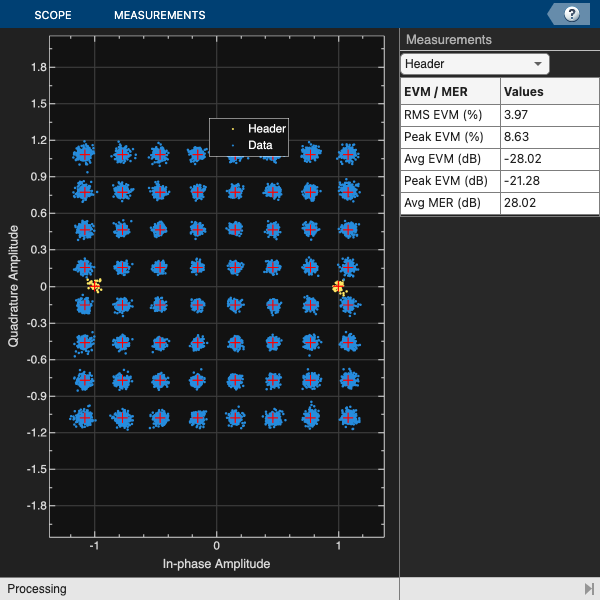

Loaded channel estimate from e3/501.mat


        if isConnected && userParam.enableScopes
            % Update the constellation diagram
            constDiag(complex(rxDiagnostics.rxConstellationHeader(:)), ...
                      complex(rxDiagnostics.rxConstellationData(:)));

            % evmCalc = comm.EVM;
            % evmPercent = evmCalc(refSymbols, rxSymbols);  % refSymbols and rxSymbols are vectors
            % fprintf('EVM = %.2f %%\n', evmPercent);
            % 
            % % Display the measurements
            % fprintf('EVM: %.2f%%\n', evmValue);
            % fprintf('MER: %.2f dB\n', merValue);
            % Force the diagram window to open and get its figure
            %constDiag.show();
            pause(.002);  % Let the figure render
            fprintf('Loaded channel estimate from %s\n', matFile);
        end

    end % frame loop

## Clear Simulation and Compute Statistics

Following frame processing, clear out state information stored in persistent variables with the `clear` command. Accumulated bit error rate and frame error rate statistics are calculated and displayed at the simulated SNR. The simulation loads the next SNR and executes another run.

    % Clear out the |persistent| variables for the sync detection flag and
    % camped flag
    clear helperOFDMRx;
    clear helperOFDMRxSearch;
    if isConnected
                    BER = errorRate(...
                sysParam.txDataBits(end-(2*sysParam.trBlkSize)+(1:sysParam.trBlkSize)), ...
                rxDataBits);
    end

    % Compute data diagnostics
    if isConnected
        FER = sum(rxDiagnostics.dataCRCErrorFlag) / length(rxDiagnostics.dataCRCErrorFlag);
        fprintf('Simulation completed at %d SNR: BER = %d, FER = %d\n',SNRdB(simLoopIdx),BER(1),FER);
        BERResults(simLoopIdx) = BER(1);
    else
 
        fprintf('Simulation completed at %d SNR: Base station not detected.\n',SNRdB(simLoopIdx));
        fprintf('\n');
        BERResults(simLoopIdx) = 0.5; % default to high BER for plotting purposes
    end

    % Release object to reconfigure for the next simulation run
    release(errorRate);
    
% SNR loop end
end

Simulation completed at 25 SNR: BER = 0, FER = 1.840491e-02


## Diagnostics

A diagnostic stucture captures various parameters for analysis during the simulation. Receiver performance can be recorded and plotted, such as the last frame's frequency offset tracking and channel estimation tracking. Error metrics like BER and FER/BLER can also be calculated and displayed.

% Plot the transmission grid
helperOFDMPlotResourceGrid(txGrid,sysParam);

% Plot the frequency offset estimator output
figure;
plot(rxDiagnostics.estCFO*sysParam.scs);
hold on;
plot(foff*fsamp*ones(length(rxDiagnostics.estCFO),1)/1e6,'--');
title('Frequency estimate');
xlabel('Sample');
ylabel('Offset (Hz)');
grid on;
legend('Estimated','Actual');


% Plot the channel estimate for one subcarrier
figure;
plot(real(rxDiagnostics.estChannel(3,:)));
hold on;
plot(imag(rxDiagnostics.estChannel(3,:)));
title('Channel estimate, subcarrier 3');
xlabel('Symbol');
ylabel('Magnitude');
grid on;
legend('Real','Imag');


% Plot a BER curve if more than one SNR was specified
if length(SNRdB) > 1
    figure;
    semilogy(SNRdB,BERResults+eps,'-*'); % add eps if no errors found
    title('BER curve');
    xlabel('SNR (dB)');
    ylabel('BER');
    grid on;
end


## Summary

This example utilizes several MATLAB System objects and functions to perform DSP and digital communications operations common within an OFDM transmission system. Various scopes and plots help visualize the signal in both time and frequency domains to evaluate receiver performance.

## Appendix

The following helper functions are used in this example:

Setup:

- [helperOFDMTxInit.m](matlab:open('./helperOFDMTxInit.m'))

- [helperOFDMRxInit.m](matlab:open('./helperOFDMRxInit.m'))

- [helperOFDMSetParameters.m](matlab:open('./helperOFDMSetParameters.m'))

Common tx/rx helpers:

- [helperOFDMGetTables.m](matlab:open('./helperOFDMGetTables.m'))

- [helperOFDMFrontEndFilter.m](matlab:open('./helperOFDMFrontEndFilter.m'))

Transmitter:

- [helperOFDMTx.m](matlab:open('./helperOFDMTx.m'))

Channel:

- [helperOFDMChannel.m](matlab:open('./helperOFDMChannel.m'))

Receiver:

- [helperOFDMRx.m](matlab:open('./helperOFDMRx.m'))

- [helperOFDMRxFrontEnd.m](matlab:open('./helperOFDMRxFrontEnd.m'))

- [helperOFDMRxSearch.m](matlab:open('./helperOFDMRxSearch.m'))

- [helperOFDMChannelEstimation.m](matlab:open('./helperOFDMChannelEstimation.m'))

- [helperOFDMFrequencyOffset.m](matlab:open('./helperOFDMFrequencyOffset.m'))

Visualization:

- [helperOFDMPlotResourceGrid.m](matlab:open('./helperOFDMPlotResourceGrid.m'))

The following helper functions can be modified to generate custom signals:

- [helperOFDMPilotSignal.m](matlab:open('./helperOFDMPilotSignal.m'))

- [helperOFDMRefSignal.m](matlab:open('./helperOFDMRefSignal.m'))

- [helperOFDMSyncSignal.m](matlab:open('./helperOFDMSyncSignal.m'))

*Copyright 2022-2024 The MathWorks, Inc.*